# BME3053C Final Project - Eczema Detection 

Authors: Megan Yip, Isha Verma

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

email: iverma@ufl.edu, megan.yip@ufl.edu

April 14th, 2021

clc; clear;

## Welcome to the Eczema Detection Program!

This program will help you determine what type of eczema or skin condition you may have.

Based on your answers to the following questions, we will tell you what type of eczema you most likely have and offer suggestions for treatment. Please be sure to consult a medical professional before starting any sort of treatment. 

Instructions: Select Yes or No for each of the following questions. Once a diagnosis is stated, do not continue selecting answers. After a diagnosis is gievn, more infomration can be found in section 5.

### Section 1

%Need to add: 
%Mayble multiple images per disease
%possible other diagnosis (i wrote alternates on "EDA Project" google doc. 
%Also consider adding ringworm, psoriasis, dandruff etc

neuro = imread('Neuro.jpg');
stasis = imread('stasis.jpg');
atopic = imread('atopic.jpg');
contact = imread('contact.jpg');
seb = imread('seb.jpg');
dys = imread('dys.jpg');
num= imread('num.jpg');


diag = "";
A = "Y";
if A== 'Y'
    B = "N"
    if B== 'Y'
        fprintf('Your diagnosis is nummular/discoid dermatitis. \n Go to section 5 to learn more about symptoms and treatment!')
        figure(1)
        imshow(num)
        diag = "num"
    elseif B=='N'
        C = "N";
        if C== 'Y'
            fprintf('Your diagnosis is dyshidrotic dermatitis or possibly contact dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            
            figure(2)
            subplot(121)
            imshow(dys)
            title('Dyshidrotic Dermatitis')
            
            hold on;
            
            subplot(122)
            imshow(contact)
            title('Contact Dermatitis')
            
            hold off;
            
            diag = "dys";
        end
    end
end

B = "N"

### Section 2

fprintf('Please skip this section if you have already received a potential diagnosis.');

Please skip this section if you have already received a potential diagnosis.

Your diagnosis is sebhorreic dermatitis. 
 Go to section 5 to learn more about symptoms and treatment!

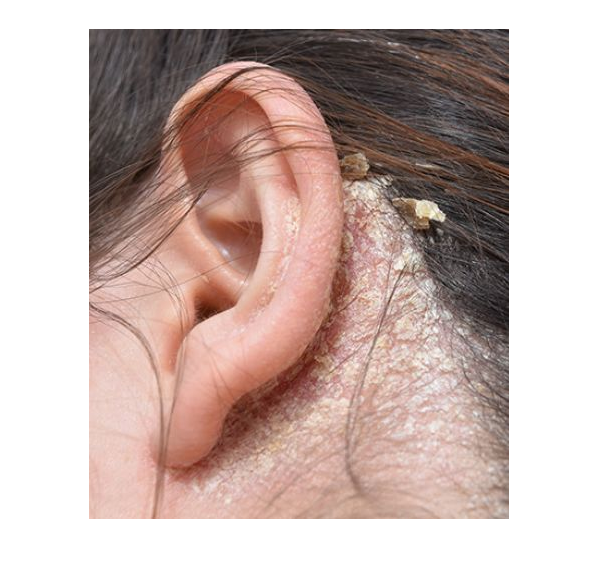

if diag ==""
    D = "Y";
    if D=='Y'
        E = "Y";
        if E == 'Y'
            fprintf('Your diagnosis is sebhorreic dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure(10)
            imshow(seb)
            diag = "seb";
        end
    end
    
end

### Section 3

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

    if diag =="" 
        F= "Select";
        if F == 'Y'
            G = "Select";
            if G == 'Y'
                H = "Select";
                if H== 'Y'
                    fprintf('Your diagnosis is stasis dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                    figure(4)
                    imshow(stasis)
                    diag = "stasis";
                end
            elseif G == 'N'                                    
                figure(5)
                subplot(141)
                imshow(stasis)
                title('AA')
                
                hold on;
    
                subplot(142)
                imshow(neuro)
                title('BB');
                
                hold on;
    
                subplot(143)
                imshow(atopic)
                title('CC')
                
                hold on;
    
                subplot(144)
                imshow(contact)
                title('DD')
                
                hold off;
                   
                    I= "Select";
                                        
                    if I == 'AA'
                        fprintf('Your diagnosis is stasis dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                        figure(6)
                        imshow(stasis)
                        diag = "stasis";
                    elseif I == 'BB'
                        fprintf('Your diagnosis is neurodermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
                        figure(7)
                        imshow(neuro)
                        diag = "neuro";
                    end 
            end
        end
        
    end

   

### Section 4

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

    if diag == ""
        J = "Select";
        
        if J == 'Y'
            fprintf('Your diagnosis is contact dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure (8)
            imshow(contact)
            diag = "contact";
        elseif J== 'N'
            fprintf('Your diagnosis is atopic dermatitis. \n Go to section 5 to learn more about symptoms and treatment!');
            figure(9)
            imshow(atopic)
            diag = "atopic";

        end
        
    end

%added an alternate case if we were unable to diagnose
if diag == ""
   fprintf("") 
end


### Section 5

%add in function here with diseases and what to do
treat = furtherSteps(diag);
fprintf(treat);

Potential diagnosis: Seborrheic Dermatisis 

Common Locations: scalp, face, sides of nose, eyebrows, ears, eyelids 

Signs and symptoms: 
     greasy looking flakes 
     red skin 

Description: Seborrheic dermatitis is a chronic type of eczema in infants and adults. It is associated with greasy flakes. 
     Thought to be an inflammatory reaction to extra Malassezia yeast. It can be triggered by medications, hormonal changes, 
     illness, stress, cold and dry weather, and harsh chemicals. 

Treatment: A skincare routine with gentle cleansers and moisturizers is helpful in managing seborrheic dermatitis. If necessary, a physician may prescribe 
     antifungal creams, medicated shampoos, or corticosteroid ointments. 

Similar conditions: Dandruff, Psoriasis 

Source: https://nationaleczema.org/eczema/types-of-eczema/seborrheic-dermatitis/

fprintf(' \n \n')

choice = "Select";
moreInfo = furtherSteps(choice);
fprintf(moreInfo);